# ENOB over Temperature

测试目的：利用热风枪改变芯片温度，利用热敏电阻反应温度变化，在变温的同时，不停地进行Calibration & A/D Conversion，从而绘制ENOB over Temperature的曲线；

clear
clc

### Reading Data from Temperature_fit.csv

result = readtable("Temperature_fit.csv", 'VariableNamingRule','preserve')

result = 120×7 table
    Prefix_index    Cycle_index     Gain     SINAD with Calibration    THD with Calibration    SINAD without Calibration    THD without Calibration
    ____________    ___________    ______    ______________________    ____________________    _________________________    _______________________

         1               1         15.271            80.52                    -94.56                     62.37                       -70.4         
         1               2         15.278            80.88                    -94.66                     62.45                      -70.54         
         1               3         15.276            80.87                    -94.09                     62.39                      -70.27         
         1               4         15.275            80.71                    -94.42                      62.4                      -70.47         
         1               5         15.276            81.02                    -94.66      

N_Temp = 12;
N_Cycle = 10;
sinad_withcalib_list = reshape(result.("SINAD with Calibration"), [N_Cycle, N_Temp])

sinad_withcalib_list =    80.5200   80.6500   79.8700   79.9100   79.7800   79.4900   79.4800   78.8900   78.3200   78.1000   76.6200   76.8100
   80.8800   80.5500   80.0600   79.7000   79.8100   79.6600   79.2700   78.8800   78.6800   77.9700   77.0100   77.4100
   80.8700   80.7200   79.7200   79.9700   80.0900   79.6600   79.4100   78.9300   78.6500   78.3600   77.7800   77.4200
   80.7100   80.4500   79.8400   79.8700   79.7700   79.4800   79.5500   79.4600   78.8700   78.6000   77.2100   77.7900
   81.0200   80.6200   79.7400   79.7900   80.0700   79.7400   79.5700   79.2100   78.7200   78.2900   77.1200   77.2400
   80.8800   80.4200   79.8100   79.9100   79.9500   79.3700   79.6800   79.0700   78.7100   78.5000   77.3300   77.3100
   80.6600   80.3900   79.5900   79.8000   80.0400   79.6000   79.4700   79.2000   78.9200   78.3500   77.0900   77.1700
   80.9400   80.4900   80.0100   79.7500   79.9300   79.3700   79.5300   79.2100   78.2100   78.1900   77.4700   76.9400
   80.620

thd_withcalib_list = reshape(result.("THD with Calibration"), [N_Cycle, N_Temp]);
gain_list = reshape(result.("Gain"), [N_Cycle, N_Temp]);
sinad_withoutcalib_list = reshape(result.("SINAD without Calibration"), [N_Cycle, N_Temp]);
thd_withoutcalib_list = reshape(result.("THD without Calibration"), [N_Cycle, N_Temp]);

## 数据后处理

Gain_mean_list = mean(gain_list);
sinad_mean_list_wi = mean(sinad_withcalib_list)

sinad_mean_list_wi =    80.7820   80.5320   79.8150   79.8060   79.9270   79.5280   79.5380   79.1260   78.6390   78.2690   77.1920   77.1710


thd_mean_list_wi = mean(thd_withcalib_list)

thd_mean_list_wi =   -94.5770  -94.8070  -93.8730  -93.4270  -93.5350  -92.2400  -91.9940  -90.9600  -90.0240  -89.0540  -87.4990  -87.4860


sinad_mean_list_wo = mean(sinad_withoutcalib_list);
thd_mean_list_wo = mean(thd_withoutcalib_list);

Temp = [30 35 40 50 60 70 80 90 100 110 120 130]

Temp =     30    35    40    50    60    70    80    90   100   110   120   130


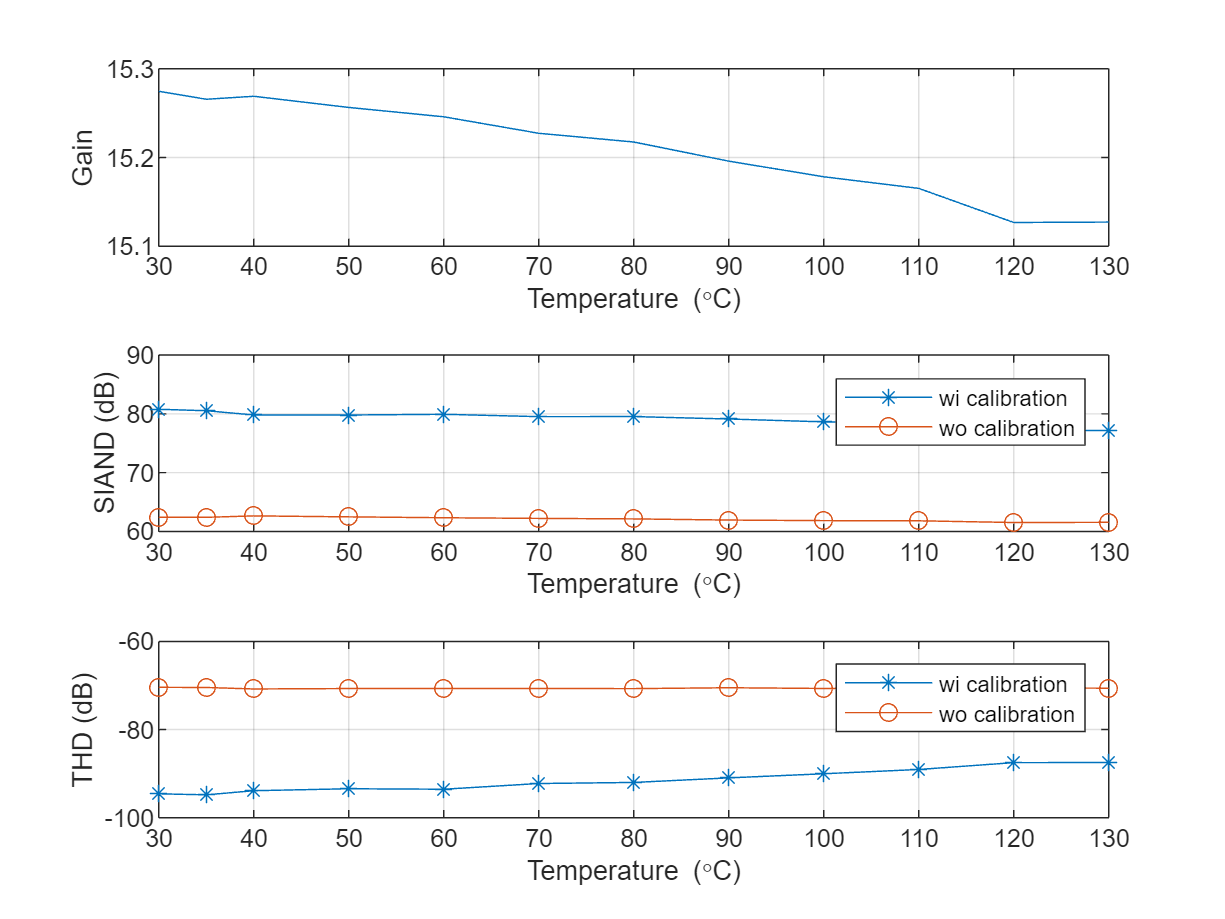

figure

tiledlayout(3,1);
nexttile
plot(Temp, Gain_mean_list)
xlabel('Temperature (\circC)');
ylabel('Gain')
grid on
nexttile
plot(Temp, sinad_mean_list_wi, '-*');
hold on;
plot(Temp, sinad_mean_list_wo, '-o');
hold off;
xlabel('Temperature (\circC)');
ylabel('SIAND (dB)')
ylim([60 90])
legend({'wi calibration', 'wo calibration'}, 'Location', 'northeast')
grid on
nexttile
plot(Temp, thd_mean_list_wi, '-*');
hold on;
plot(Temp, thd_mean_list_wo, '-o');
hold off;
xlabel('Temperature (\circC)');
ylabel('THD (dB)')
ylim([-100 -60])
legend({'wi calibration', 'wo calibration'}, 'Location', 'northeast')
grid on

## 数据验证与扫描增益参数

- SINAD、THD关于增益扫描参数；

- ENOB of Flash

ENOB_ideal = 5 + 3*log2(Gain_mean_list)

ENOB_ideal =    16.7992   16.7967   16.7976   16.7940   16.7911   16.7858   16.7830   16.7768   16.7718   16.7681   16.7571   16.7572


sinad_idea = 6.02*ENOB_ideal - 1.72

sinad_idea =    99.4111   99.3958   99.4016   99.3801   99.3621   99.3304   99.3135   99.2766   99.2464   99.2239   99.1579   99.1586
